# 0.环境清理

close all;
clear;
clc;

# 1.文件夹路径

file_path   =   'D:\DATA\omni_hig_res';
file_name   =   'omni_min2015.asc';

# 2.读取数据

time_begin  =   datetime(2015,12,11,0,0,0);
time_end    =   datetime(2015,12,12,0,0,0);
var_list    =   {'AE','AL'};
data = readYearData(file_path,file_name,time_begin,time_end,var_list);

#  3.数据展示

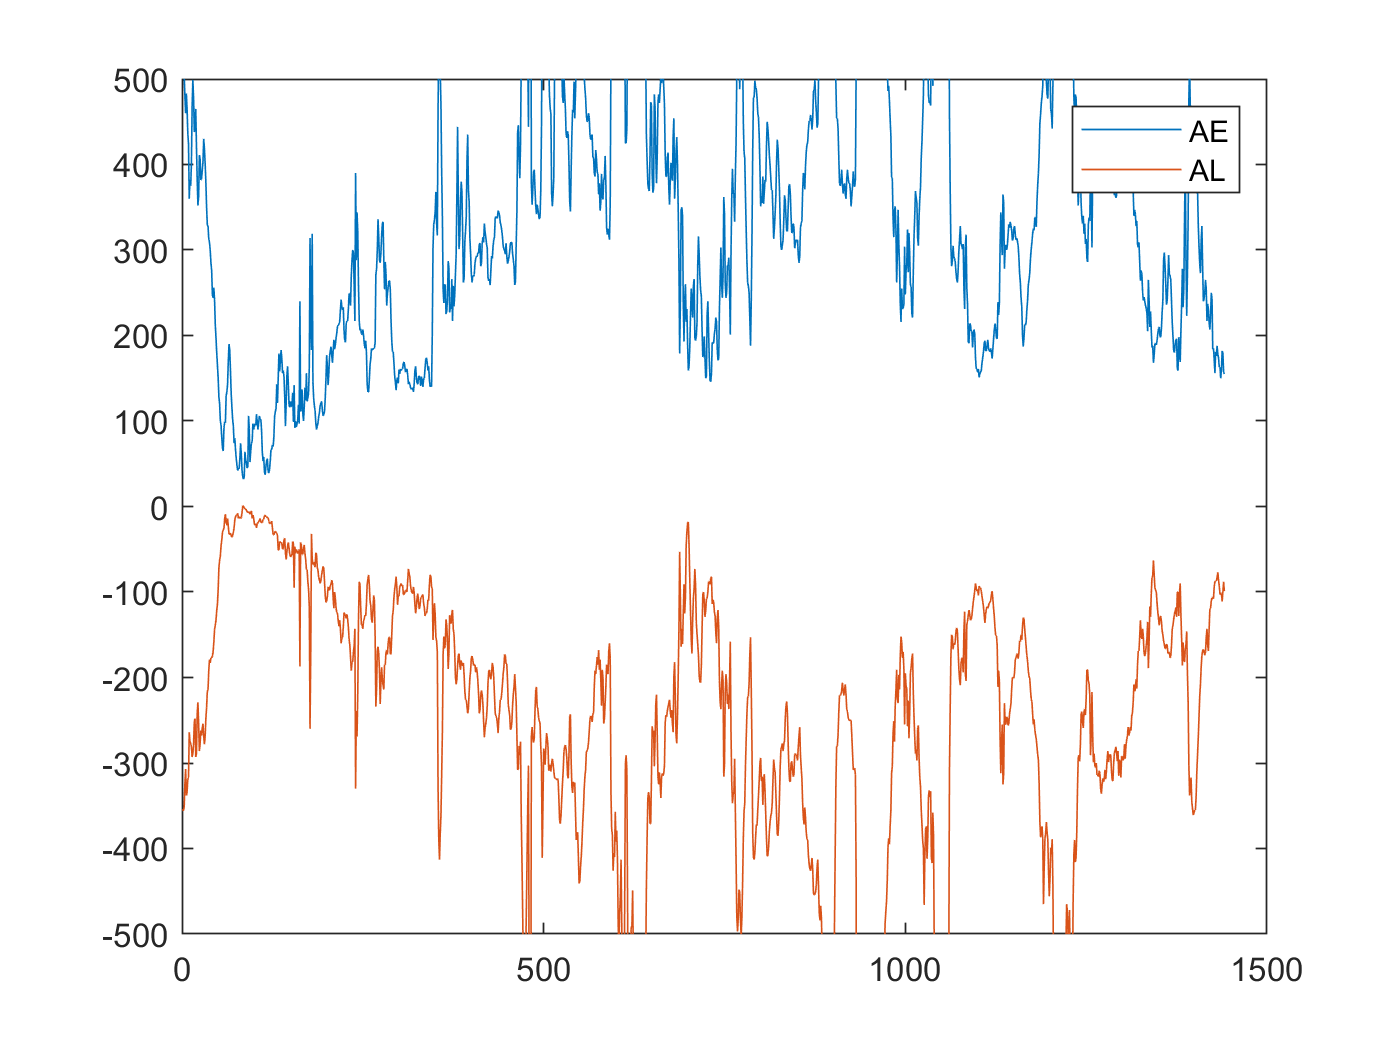

figure();
length = size(data,2);
plot(1:length,[data{2,:}]);
hold on;
plot(1:length,[data{3,:}]);
legend({'AE','AL'});
ylim([-500,500]);